## Supplementary 3 

clear all; close all; clc;

%add the source data
addpath 'path\to\data_source';
addpath 'path\to\INTHIS\DataAnalysis';


## Run simulink simulation

%typical case
tpulse=0.001; %1 ms pulse duration
    
%run simulink m8 for figure;
out=sim("Supplementary3.slx");

% get signals
t1=out.tout;
X1=out.simout;

%doubled crowd
tpulse=0.002; %2 ms pulse duration
    
%run simulink for figure;
out=sim("Supplementary3.slx");

% get signals
t2=out.tout;
X2=out.simout;

%triple crowd
tpulse=0.003; %3 ms pulse duration
    
%run simulink m8 for figure;
out=sim("Supplementary3.slx");

% get signals
t3=out.tout;
X3=out.simout;

## Subfigure 1

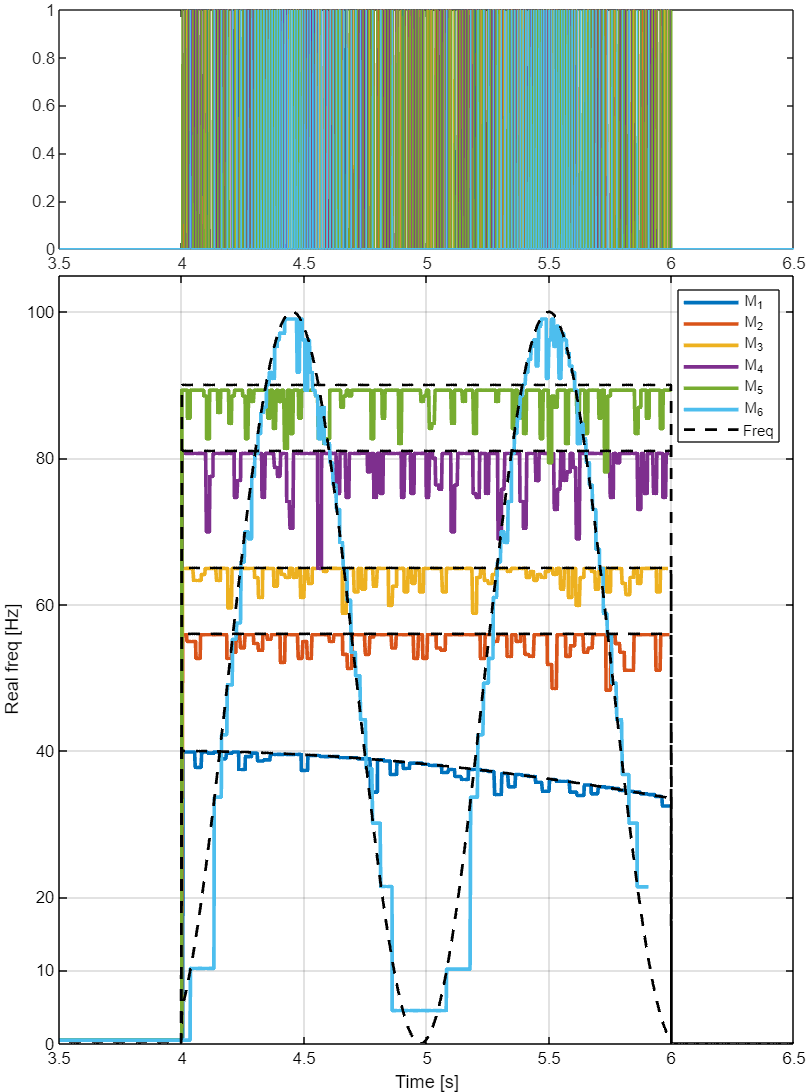

%% get signals
sub1=figure('Units','centimeters','Position',[0 0 15.5 21]); 
tiledlayout(4,1,"TileSpacing","tight","Padding","tight");

%% compute frequencies
t=t1;
X=X1;

nexttile; axis off; plot(t,X,'LineWidth',0.5);
xlim([3.5 6.5]);
Cmap = colororder(gcf);

%adjust time
td=t(1:end-1);

%get the rising edges of the pulses with a discrete I order derivative
Xd=X(2:end,:)-X(1:end-1,:);
Xd(Xd<=0)=0;

nexttile([3 1]); hold on;
ylim([0 105]); yticks([0 10 20:20:105]); ylabel('Real freq [Hz]');
for i=1:size(X,2)
    
    %initialize freqs
    freqs=nan(size(td));
    
    %find the t of rising edges
    edges=td(Xd(:,i)==1);
    
    %find the deltat between adjacent t
    diffs=edges(2:end)-edges(1:end-1); 
    diffs=[diffs; 0];
    
    %istantaneous frequency is inversion of deltat
    freqs(Xd(:,i)==1)=1./diffs;
    freqt=freqs(~isnan(freqs));
    freqsint=fillmissing(freqs,"previous");
    
    %report
    plot(td,freqsint,'LineWidth',2);  grid on; box on;
    %scatter(edges, freqt,5,'filled','o','k');
end
plot(t,out.simout1,'--k','LineWidth',1.5); xlabel('Time [s]'); box on;
xlim([3.5 6.5]);
hold off; legend('M_1','M_2','M_3','M_4','M_5','M_6','Freq');
recolorfig();
%export
saveas(sub1,fullfile("subfigures","sub1.fig"));
exportgraphics(sub1, fullfile("subfigures","sub1.png"), 'ContentType', 'image','Resolution',300);
exportgraphics(sub1, fullfile("subfigures","sub1.pdf"), 'ContentType', 'vector', 'BackGroundColor', 'none','Resolution',300);

## Subfigure 2-3

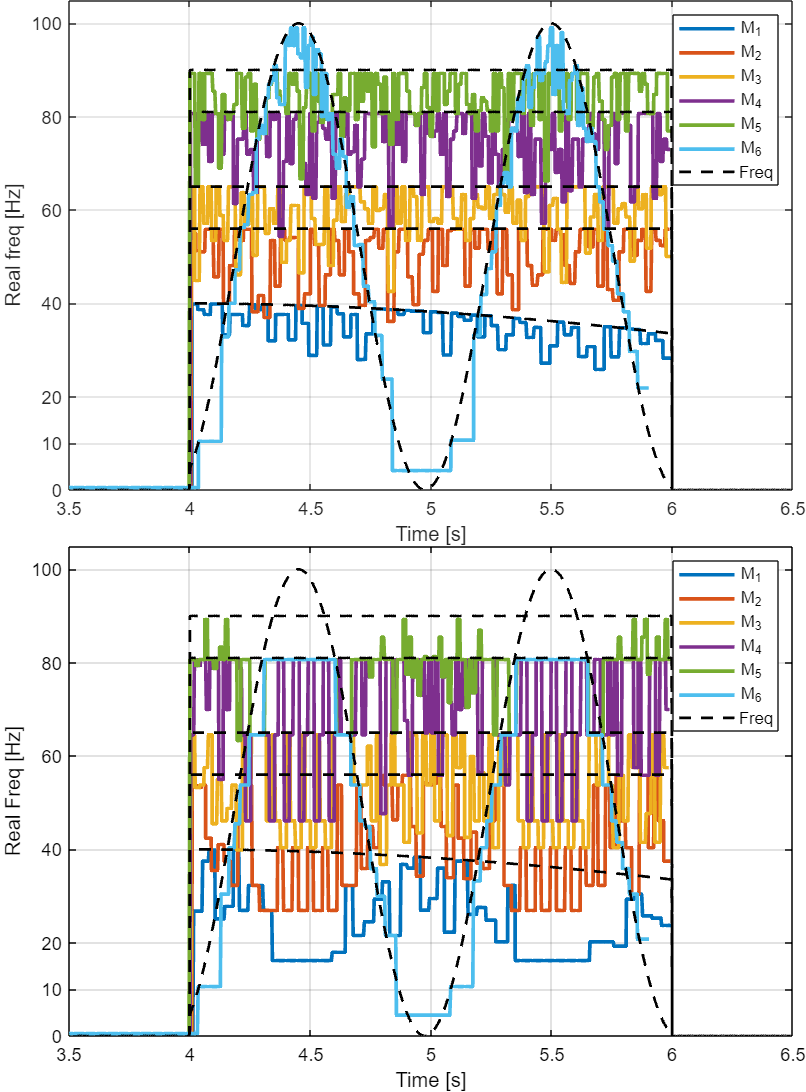

%% get signals
sub23=figure('Units','centimeters','Position',[0 0 15.5 21]); 
tiledlayout(2,1,"TileSpacing","tight","Padding","tight");
Cmap = colororder(gcf);

%% compute frequencies
t=t2;
X=X2;

%adjust time
td=t(1:end-1);

%get the rising edges of the pulses with a discrete I order derivative
Xd=X(2:end,:)-X(1:end-1,:);
Xd(Xd<=0)=0;

nexttile(); hold on;
ylim([0 105]); yticks([0 10 20:20:105]); ylabel('Real freq [Hz]');
for i=1:size(X,2)
    
    %initialize freqs
    freqs=nan(size(td));
    
    %find the t of rising edges
    edges=td(Xd(:,i)==1);
    
    %find the deltat between adjacent t
    diffs=edges(2:end)-edges(1:end-1); 
    diffs=[diffs; 0];
    
    %istantaneous frequency is inversion of deltat
    freqs(Xd(:,i)==1)=1./diffs;
    freqt=freqs(~isnan(freqs));
    freqsint=fillmissing(freqs,"previous");
    
    %report
    plot(td,freqsint,'LineWidth',2);  grid on; box on;
    %scatter(edges, freqt,5,'filled','o','k');
end
plot(t,out.simout1,'--k','LineWidth',1.5); xlabel('Time [s]'); box on;
xlim([3.5 6.5]);
hold off; legend('M_1','M_2','M_3','M_4','M_5','M_6','Freq');

%% compute frequencies
t=t3;
X=X3;

%adjust time
td=t(1:end-1);

%get the rising edges of the pulses with a discrete I order derivative
Xd=X(2:end,:)-X(1:end-1,:);
Xd(Xd<=0)=0;

nexttile(); hold on;
ylim([0 105]); yticks([0 10 20:20:105]); ylabel('Real Freq [Hz]');
for i=1:size(X,2)
    
    %initialize freqs
    freqs=nan(size(td));
    
    %find the t of rising edges
    edges=td(Xd(:,i)==1);
    
    %find the deltat between adjacent t
    diffs=edges(2:end)-edges(1:end-1); 
    diffs=[diffs; 0];
    
    %istantaneous frequency is inversion of deltat
    freqs(Xd(:,i)==1)=1./diffs;
    freqt=freqs(~isnan(freqs));
    freqsint=fillmissing(freqs,"previous");
    
    %report
    plot(td,freqsint,'LineWidth',2);  grid on; box on;
    %scatter(edges, freqt,5,'filled','o','k');
end
plot(t,out.simout1,'--k','LineWidth',1.5); xlabel('Time [s]'); box on;
xlim([3.5 6.5]);
hold off; legend('M_1','M_2','M_3','M_4','M_5','M_6','Freq');

recolorfig();
%export
saveas(sub23,fullfile("subfigures","sub23.fig"));
exportgraphics(sub23, fullfile("subfigures","sub23.png"), 'ContentType', 'image','Resolution',300);
exportgraphics(sub23, fullfile("subfigures","sub23.pdf"), 'ContentType', 'vector', 'BackGroundColor', 'none','Resolution',300);

Supplementary3;
print('-sSupplementary3','-dpdf',fullfile('subfigures','model.pdf'));